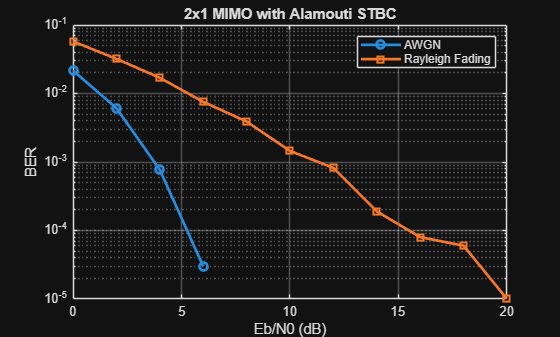

clc; clear; close all;

%% Parameters
N = 1e5;                  % Number of bits
EbN0_dB = 0:2:20;

% BPSK
bits = randi([0 1], N, 1);
symbols = 2*bits - 1;

% Group symbols in pairs
symbols = reshape(symbols, 2, []);

ber_awgn = zeros(size(EbN0_dB));
ber_rayleigh = zeros(size(EbN0_dB));

%% ================= Simulation =================
for i = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(i)/10);
    noise_var = 1/(2*EbN0);
    
    err_awgn = 0;
    err_ray = 0;
    
    for k = 1:size(symbols,2)
        
        s1 = symbols(1,k);
        s2 = symbols(2,k);
        
        %% ================= AWGN =================
        % No fading → channel = 1
        h1 = 1; h2 = 1;
        
        n1 = sqrt(noise_var)*(randn + 1j*randn);
        n2 = sqrt(noise_var)*(randn + 1j*randn);
        
        % Time slot 1
        y1 = h1*s1 + h2*s2 + n1;
        
        % Time slot 2
        y2 = -h1*conj(s2) + h2*conj(s1) + n2;
        
        % Combining
        r1 = conj(h1)*y1 + h2*conj(y2);
        r2 = conj(h2)*y1 - h1*conj(y2);
        
        % Decision
        s1_hat = real(r1) > 0;
        s2_hat = real(r2) > 0;
        
        if s1_hat ~= (s1>0), err_awgn = err_awgn + 1; end
        if s2_hat ~= (s2>0), err_awgn = err_awgn + 1; end
        
        %% ================= Rayleigh =================
        h1 = (randn + 1j*randn)/sqrt(2);
        h2 = (randn + 1j*randn)/sqrt(2);
        
        n1 = sqrt(noise_var)*(randn + 1j*randn);
        n2 = sqrt(noise_var)*(randn + 1j*randn);
        
        % Time slot 1
        y1 = h1*s1 + h2*s2 + n1;
        
        % Time slot 2
        y2 = -h1*conj(s2) + h2*conj(s1) + n2;
        
        % Combining
        r1 = conj(h1)*y1 + h2*conj(y2);
        r2 = conj(h2)*y1 - h1*conj(y2);
        
        % Normalize
        norm_factor = abs(h1)^2 + abs(h2)^2;
        r1 = r1 / norm_factor;
        r2 = r2 / norm_factor;
        
        % Decision
        s1_hat = real(r1) > 0;
        s2_hat = real(r2) > 0;
        
        if s1_hat ~= (s1>0), err_ray = err_ray + 1; end
        if s2_hat ~= (s2>0), err_ray = err_ray + 1; end
        
    end
    
    ber_awgn(i) = err_awgn / N;
    ber_rayleigh(i) = err_ray / N;
    
end

%% ================= Plot =================
figure;
semilogy(EbN0_dB, ber_awgn, 'o-', 'LineWidth', 2); hold on;
semilogy(EbN0_dB, ber_rayleigh, 's-', 'LineWidth', 2);

grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title('2x1 MIMO with Alamouti STBC');
legend('AWGN','Rayleigh Fading');